import mlreportgen.dom.*
cd ('C:\Users\dml36958\Desktop\STFC_Gits\HEXITEC')
D = Document('FromTemplate','docx','Template.dotx')

D =   Document with properties:

           OutputPath: 'C:\Users\dml36958\Desktop\STFC_Gits\HEXITEC\FromTemplate'
          PackageType: 'zipped'
       ForceOverwrite: 1
         StreamOutput: 0
         TitleBarText: ''
          HTMLHeadExt: ''
         TemplatePath: 'Template.dotx'
                 Type: 'DOCX'
        CurrentHoleId: ''
      CurrentHoleType: ''
    CurrentPageLayout: []
           OpenStatus: 'unopened'
               Parent: []
             Children: [1×0 mlreportgen.dom.Node]
                  Tag: 'dom.Document:5723'
                   Id: '5723'


open(D)

ans = logical
   1



% Title Page Sequence
moveToNextHole(D)

ans = 'TileBox'

titleText = Text('Detectors for Illinois', 'Title Style');
append(D, titleText)

ans =   Text with properties:

             Content: 'Detectors for Illinois'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Title Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:5747'
                  Id: '5747'



moveToNextHole(D)

ans = 'AuthorBox'

authorText = Text('Rhian Mair Wheater', 'Heading Style');
append(D, authorText)

ans =   Text with properties:

             Content: 'Rhian Mair Wheater'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Heading Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:5752'
                  Id: '5752'



moveToNextHole(D)

ans = 'DateBox'

today = date;
dateText = Text(today, 'Heading Style')

dateText =   Text with properties:

             Content: '23-Sep-2020'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Heading Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:5757'
                  Id: '5757'


append(D, dateText)

ans =   Text with properties:

             Content: '23-Sep-2020'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Heading Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:5757'
                  Id: '5757'



% Testing Conditions Sequence
biasV = -750; % in V
temp = 28; % in degrees C
xraySource = 'Am-241';
duration = 5; % in minutes

biasVoltageStr = strcat('Applied bias voltage of ', num2str(biasV));
tempStr = strcat('Detector temperature maintained at ', num2str(temp), '^{o}C');
durationStr = strcat('Exposure to an ',xraySource,' source for a duration of ', num2str(duration),' minutes');
conditionsList = UnorderedList({biasVoltageStr; tempStr; durationStr})

conditionsList =   UnorderedList with properties:

           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×3 mlreportgen.dom.ListItem]
                 Tag: 'dom.UnorderedList:5759'
                  Id: '5759'


conditionsList.StyleName = 'Bulk Style'

conditionsList =   UnorderedList with properties:

           StyleName: 'Bulk Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×3 mlreportgen.dom.ListItem]
                 Tag: 'dom.UnorderedList:5759'
                  Id: '5759'


moveToNextHole(D)

ans = 'TestConditons'

append(D, conditionsList)

ans =   UnorderedList with properties:

           StyleName: 'Bulk Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×3 mlreportgen.dom.ListItem]
                 Tag: 'dom.UnorderedList:5759'
                  Id: '5759'



% Importing Figures Sequence
analysedFilesLocation = 'I:\Illinois\CZT_loan\Kromek'

analysedFilesLocation = 'I:\Illinois\CZT_loan\Kromek'

analysedFiles = dir(analysedFilesLocation);
analysedFiles = analysedFiles(3:length(analysedFiles));
moveToNextHole(D)

ans = 'Detector Analysis'

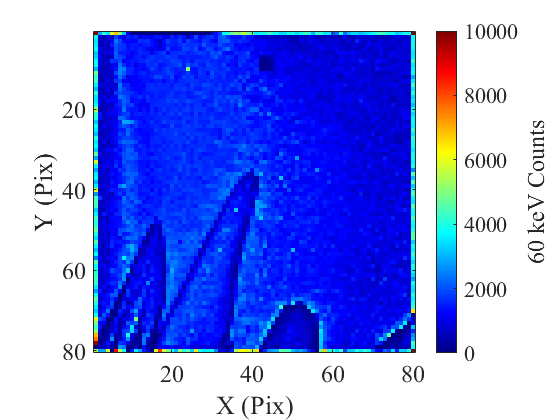

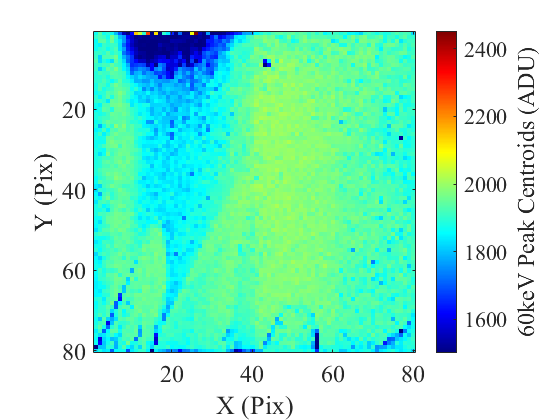

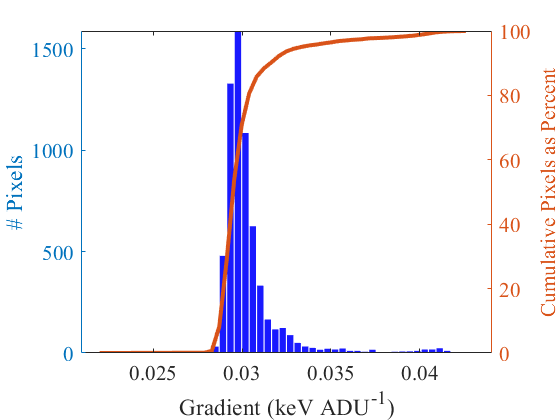

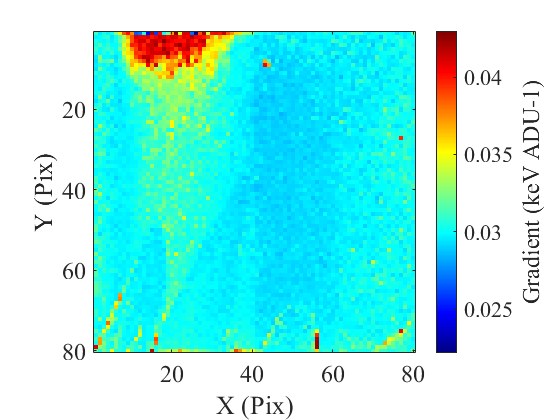

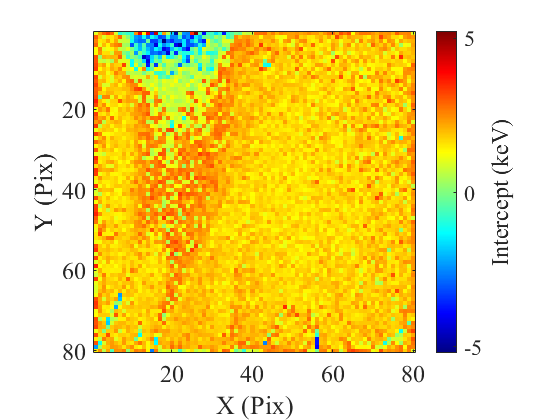

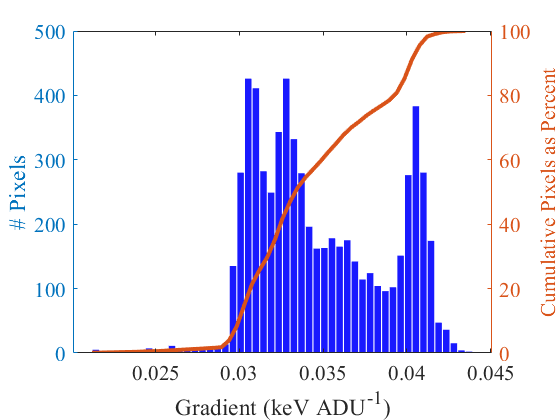

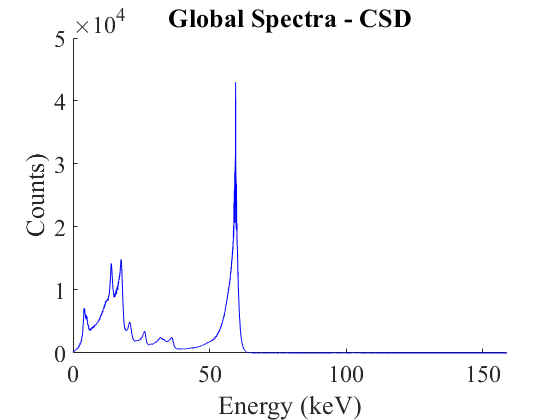

for ii =1:length(analysedFiles)-1    
    cd (strcat(analysedFilesLocation,'\',analysedFiles(ii).name));
    figuresLocation = dir('Figures*');
    cd (figuresLocation.name);
    
    resultsDirectory = strcat(analysedFilesLocation,'\',analysedFiles(ii).name,'\',figuresLocation.name,'\');
    detectorID = Text(analysedFiles(ii).name, 'Detector Heading Style');
    append (D, detectorID);
    
    fig = open(strcat(resultsDirectory,'Image60keV.fig'));
    saveas(fig, strcat(resultsDirectory,'figure1.png'));
    docuFig = Image(strcat(resultsDirectory,'figure1.png'));
    docuFig.Style = {Height('4in')};
    append(D, docuFig);

    fig = open(strcat(resultsDirectory,'peakCents_60keV.fig'));
    saveas(fig, strcat(resultsDirectory,'figure2.png'));
    docuFig = Image(strcat(resultsDirectory,'figure2.png'));
    docuFig.Style = {Height('4in')};
    append(D, docuFig);

    fig = open(strcat(resultsDirectory,'GradientHistogram.fig'));
    saveas(fig, strcat(resultsDirectory,'figure3.png'));
    docuFig = Image(strcat(resultsDirectory,'figure3.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig);
    
    fig = open(strcat(resultsDirectory,'Gradients.fig'));
    saveas(fig, strcat(resultsDirectory,'figure4.png'));
    docuFig = Image(strcat(resultsDirectory,'figure4.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig);    

    fig = open(strcat(resultsDirectory,'InterceptsHistogram.fig'));
    saveas(fig, strcat(resultsDirectory,'figure5.png'));
    docuFig = Image(strcat(resultsDirectory,'figure5.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig);      
    
    fig = open(strcat(resultsDirectory,'Intercepts.fig'));
    saveas(fig, strcat(resultsDirectory,'figure6.png'));
    docuFig = Image(strcat(resultsDirectory,'figure6.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig);  
    
    fig = open(strcat(resultsDirectory,'CalibratedGlobalCSDplot.fig'));
    saveas(fig, strcat(resultsDirectory,'figure7.png'));
    docuFig = Image(strcat(resultsDirectory,'figure7.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig);  
    
    fig = open(strcat(resultsDirectory,'CalibratedCSDplotPixel4040.fig'));
    saveas(fig, strcat(resultsDirectory,'figure8.png'));
    docuFig = Image(strcat(resultsDirectory,'figure8.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig); 
    
    
    
%     fig1 = open(strcat(resultsDirectory,'GradientHistogram.fig'));
%     fig2 = open(strcat(resultsDirectory,'Gradients.fig'));    
%     saveas(fig1, strcat(resultsDirectory,'figure3.png'));
%     saveas(fig2, strcat(resultsDirectory,'figure4.png'));
%     
%     fig1Im = Image(strcat(resultsDirectory,'figure3.png'));
%     fig2Im = Image(strcat(resultsDirectory,'figure4.png'));
%     fig1Im.Style = {Height('3in')};
%     fig2Im.Style = {Height('2.5in')};
% 
%     lo_table=Table({fig1Im, fig2Im});
%     append(D, lo_table)
    append(D, PageBreak);
 end


cd ('C:\Users\dml36958\Desktop\STFC_Gits\HEXITEC')
close(D)

ans = logical
   1
